此函数的简短摘要。

此函数的详细说明。

clear,clc
close all

环境设置


num_user_all = [10] ; 
for index_user = 1:length(num_user_all)
     num_user =num_user_all(index_user);


x_Jammer=5; 
y_Jammer=5;

[x_user,y_user]=coa_loc_chushihua(num_user);


参数设置

R=10; 
h=1;  
V_th=1e6;
P_user=[1 3 5 7];  
P_Jammer=100;  
B=1e7;  
N0=2;
lossexponent_user=1;  
lossexponent_jammer=1;  

num_coal=3; 
JammChan=1; 


P_t=P_user(2)*1; 



ITE=30;    

for m=1:ITE  
    coalition=coa_chushihua(num_user); 
  
% n1=randperm(num_user,1);  
 



  for  n1=1:num_user
        rew=zeros(length(coalition),1); 
        for n4=1:length(coalition) 
             if  n4==1
                 P_J=P_Jammer;
             else
                 P_J=0;
             end
          
             sumc=fun_coa_rate(coalition{n4},P_t,N0,P_J,x_user,y_user); 
             rew(n4)=sumc;
       end
        reward(m)=sum(rew);  
        

        
        conum=zeros(num_user,1);
      
        KCO=length(coalition);
        
        for i=1:num_user
            for k=1:KCO
                if ismember(i,coalition{k})
                    conum(i)=k;  
                    break
                end
            end
        end
        current_co=coalition{conum(n1)};  
       
       
        k=conum(n1);  
        P_J = P_ganrao(current_co,k,P_Jammer);
        u01=fun_coa_rate(current_co,P_t,N0,P_J,x_user,y_user); 
        delta=setdiff(current_co,n1); 
        u02=fun_coa_rate(delta,P_t,N0,P_J,x_user,y_user);
        u0=u01-u02;
      
        
         neighbor_set=setdiff([1:3],conum(n1)); 
          
        
        if isempty(neighbor_set)  
            continue;
        end
        
        if ~isempty(neighbor_set)
            
            rt=zeros(length(neighbor_set),2);
          
            for n2=1:length(neighbor_set)    
      
               target_co=coalition{(neighbor_set(n2))};  
              
                k=(neighbor_set(n2)); 
                P_J = P_ganrao(target_co,k,P_Jammer);
               
                u10=fun_coa_rate(target_co,P_t,N0,P_J,x_user,y_user);
            
                target_coa=union(target_co,n1); 
                P_J = P_ganrao(target_coa,k,P_Jammer);
                
                u11=fun_coa_rate(target_coa,P_t,N0,P_J,x_user,y_user);
                u1=u11-u10;
                rt(n2,1)=u1-u0;  
            
             [mrt,index]=max(rt(:,1));
            
        end
        

      if mrt<=0         
           disp('Something happened')
        else
        % if u11+u02 >= u10+u01  &&  u1>=u0 % Pareto 
        % if u11+u02 >= u10+u01   % selfish
            
                coalition{conum(n1)}=setdiff(coalition{conum(n1)},n1);
                findco=coalition{neighbor_set(index)};
              
                findco=union(findco,n1);
                coalition{neighbor_set(index)}=findco;
        %  end
       end         
       
   end
    
   result{m}=coalition; 
   
    if m ==1
        R_max = reward(1);
    end
    if m>1
        if reward(m)>R_max(m-1)
    R_max(m) = reward(m);
        end
        if reward(m)<=R_max(m-1)
    R_max(m) = R_max(m-1);
        end
    end
  
    Reward_All_User(index_user) = max(reward);
    data=['Reward_All_User','.mat'];
    save(data,'Reward_All_User')

end % user number的end

Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something happened
Something ha

end
end
 

画图


R_max_mean=mean(R_max);
R=max(R_max)

R = 1.9301e+07

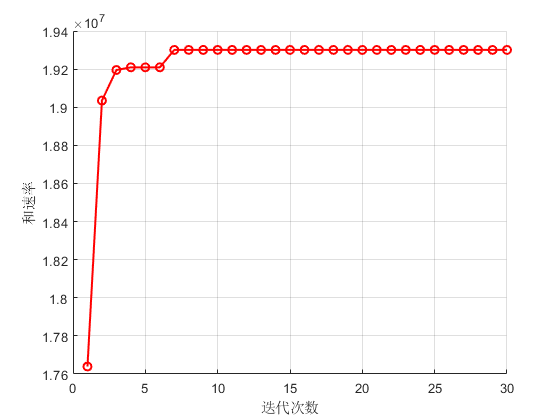

figure
 hold on
plot(R_max,'co-','LineWidth',1.5,'MarkerSize',6);hold on
plot(R_max,'ro-','LineWidth',1.5,'MarkerSize',6)
xlabel('迭代次数')
ylabel('和速率')
grid on